# 3.4.5 Problem 2

## Author: Tomoki Koike

#### Load the data sunspot.dat and analyze the data to find the period of the sunspot activity.

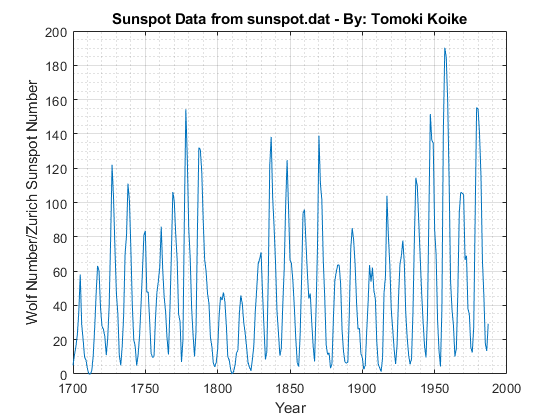

clear all
close all
clc

load sunspot.dat  % Loading the sunspot.dat file
year = sunspot(:,1);  % Assigning the first column into a year vector
wolf = sunspot(:,2);  % Assigning the the second column into a wolf number vector

% Plotting the given data
figure(1)
plot(year, wolf)
xlabel('Year')
ylabel('Wolf Number/Zurich Sunspot Number')
title('Sunspot Data from sunspot.dat - By: Tomoki Koike')
grid on
grid minor
box on

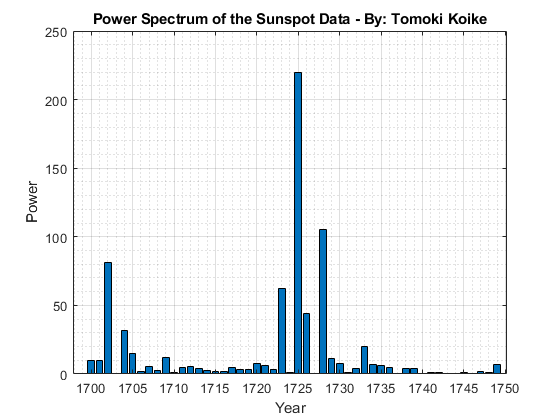


% Using the ifft to find the a-matrix
wolf = wolf - mean(wolf);  % Taking out the a0 term or the mean
a = ifft(wolf);
figure(2)
bar((1699:1749), abs(a(1:51)).^2)
xlabel('Year')
ylabel('Power')
title('Power Spectrum of the Sunspot Data - By: Tomoki Koike')
grid on
grid minor
box on


% Finding the maximum power and its index to find the period of the
% sunspots
pow = abs(a(1:51)).^2;
tot_years = length(year);  % The tau value for these data 
[max_pow, idx] = max(pow);  % Obtaining the index of the maximum power
sunspot_p = tot_years / idx;

## Answer

fprintf(['The period of the sunspot data from ' ...
    'sunspot.dat is %.3f years.'], sunspot_p);

The period of the sunspot data from sunspot.dat is 10.667 years.